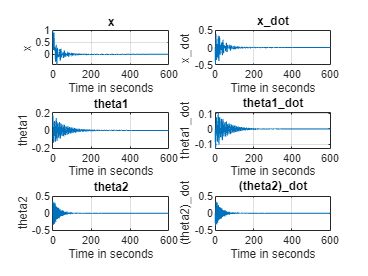

%Definiing the time span for simulating the system with initial conditions 
t_span = 0:0.01:600;
y0 = [1; 0; deg2rad(10); 0; deg2rad(20); 0];

%Function to simulate the Non Linear System
[ts, x_dot] = ode45(@non_lin_sys, t_span, y0);

%Plotting the Results of the system
figure
subplot(3, 2, 1)
plot(ts, x_dot(:, 1))
title('x')
xlabel('Time in seconds')
ylabel('x')
grid on

subplot(3, 2, 2)
plot(ts, x_dot(:, 2))
title('x\_dot')
xlabel('Time in seconds')
ylabel('x\_dot')
grid on

subplot(3, 2, 3)
plot(ts, x_dot(:, 3))
title('theta1')
xlabel('Time in seconds')
ylabel('theta1')
grid on

subplot(3, 2, 4)
plot(ts, x_dot(:, 4))
title('theta1\_dot')
xlabel('Time in seconds')
ylabel('theta1\_dot')
grid on

subplot(3, 2, 5)
plot(ts, x_dot(:, 5))
title('theta2')
xlabel('Time in seconds')
ylabel('theta2')
grid on

subplot(3, 2, 6)
plot(ts, x_dot(:, 6))
title('(theta2)\_dot')
xlabel('Time in seconds')
ylabel('(theta2)\_dot')
grid on

function ydot = non_lin_sys(~, x)
    

    % Declaring the values of system variables
    M = 1000;
    m1 = 100;
    m2 = 100;
    l1 = 20;
    l2 = 10;
    g = 9.81;
    
    % Declaring the A matrix of the system
    A=[0 1 0 0 0 0;
        0 0 (-m1*g/M) 0 (-m2*g/M) 0;
        0 0 0 1 0 0;
        0 0 ((-g*(M+m1))/(l1*M)) 0 ((-g*m2)/(l1*M)) 0;
        0 0 0 0 0 1;
        0 0 ((-g*m1)/(l2*M)) 0 ((-g*(M+m2))/(l2*M)) 0];
        
    % Declaring the B matrix of the system
    B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
    
    C=[1 0 0 0 0 0 ];
    % Defining the Q and R matrices for LQR controller
    Q=[10 0 0 0 0 0;
        0 10 0 0 0 0 ;
        0 0 200 0 0 0;
        0 0 0 200 0 0;
        0 0 0 0 200 0;
        0 0 0 0 0 200];
    
    R=0.001;

    K = lqr(A,B,Q,R);
    f = -K*x;
    
    poles=[-1;-2;-3;-4;-5;-6];
    %Luenberger Observer Gains

    %Observer State Estimates
    L=place(A',C', poles)';
    

    ydot = zeros(6,1);
    % State x_dot_1 is x_2
    ydot(1) = x(2);
    % State x_dot_2 is 
    ydot(2) = (f - (g/2)*(m1*sin(2*x(3)) + m2*sin(2*x(5))) - (m1*l1*(x(4)^2)*sin(x(3))) - (m2*l2*(x(6)^2)*sin(x(5)))) / (M+m1*((sin(x(3)))^2)+m2*((sin(x(5)))^2));
    % State x_dot_3 is theta 1
    ydot(3) = x(4);
    % State x_dot_4 is theta1 dot
    ydot(4) = (ydot(2)*cos(x(3)) - g*(sin(x(3))))/l1;
    % State x_dot_5 is theta2
    ydot(5) = x(6);
    % State x_dot_6 is theta2 dot
    ydot(6) = (ydot(2)*cos(x(5)) - g*(sin(x(5))))/l2;

end




